# m0503_plotmnttrajactory_carmaker

This script is used to visualize the position of all the inertial sensors at each mounting point (mnt).  

## Select the data range

Time(end)

ans = 9.5640

length_t = size(Time,1) %check number of rolls

length_t = 9565

Time(length_t)

ans = 9.5640

%Define range of samples to plot for plotting
t_range_perc = [0.001 1]% range of time to plot in fraction

t_range_perc =     0.0010    1.0000


sample_start = round(length_t*t_range_perc(1,1))+1

sample_start = 11

sample_end = round(length_t*t_range_perc(1,2))

sample_end = 9565

t_plot = Time(sample_start:sample_end);



## Plot the data in x-y plane

figure(1)
clf
plot(MntFL_x_m,MntFL_y_m)
xlabel('x')
ylabel('y')

xl = xlim

xl =    -20   100


yl = ylim

yl =    -30    40



xl_range = xl(1,2) - xl(1,1)

xl_range = 120

yl_range = yl(1,2) - yl(1,1)

yl_range = 70

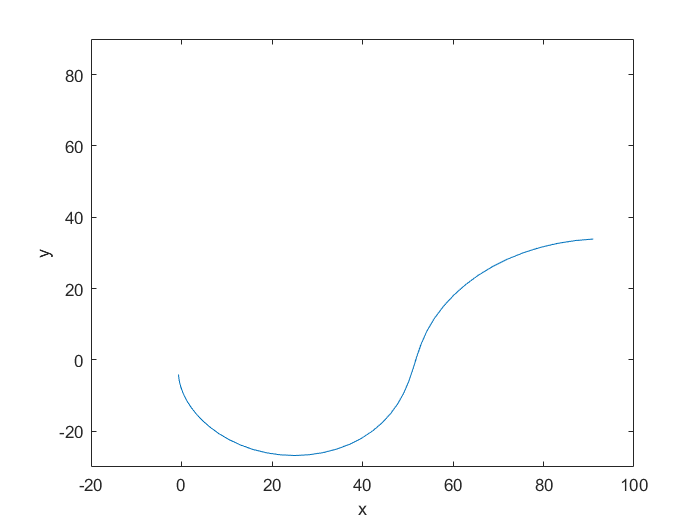

yl =    -30    90



if (xl_range > yl_range)
    yl(1,2) = yl(1,1) + xl_range
    ylim(yl)
else
    xl(1,2) = xl(1,1) + yl_range
    xlim(xl)
end

## Plot the data in 3D

figure(1)
clf
plot3(MntFL_x_m,MntFL_y_m,MntFL_z_m,MntFR_x_m,MntFR_y_m,MntFR_z_m,MntR_x_m,MntR_y_m,MntR_z_m)
xlabel('x')
ylabel('y')
zlabel('z')
legend("Front Left", "Front Right", "Rear")

xl = xlim

xl =    -2.3385  100.0000


yl = ylim

yl =    -40    40


zl = zlim

zl =     0.5500    0.7500



xl_range = xl(1,2) - xl(1,1)

xl_range = 102.3385

yl_range = yl(1,2) - yl(1,1)

yl_range = 80

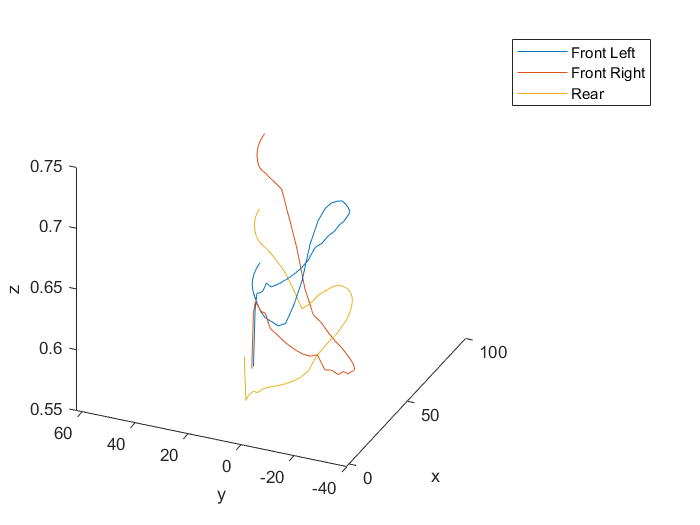

yl =   -40.0000   62.3385



if (xl_range > yl_range)
    yl(1,2) = yl(1,1) + xl_range
    ylim(yl)
%     zl(1,2) = zl(1,1) + xl_range
%     zlim(zl)
else
    xl(1,2) = xl(1,1) + yl_range
    xlim(xl)
%     zl(1,2) = zl(1,1) + yl_range
%     zlim(zl)
end


%% Plot t
